clear all
clc
close all
t = 0:15;
f = [0 0 0 1 0 0 1 0 0 0 0 1 1 1 0 1 ];
f_bar = [0 1 0 0 0 1 1 1 0 1 0 0 1 0 0 0 ];


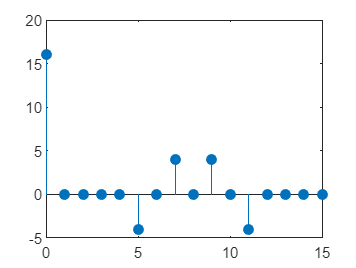

%periodic sequence
%set autocorrelations for f

reg_plus_f_auto = zeros(1,16);
reg_shift = f;


for k = 1:16
    for i = 1:16
        if(reg_shift(i) == f(i));
            reg_plus_f_auto(1,k) = reg_plus_f_auto(1,k) + 1;
        else (reg_shift(i) ~= f(i));
            reg_plus_f_auto(1,k) = reg_plus_f_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_f_auto,"filled");

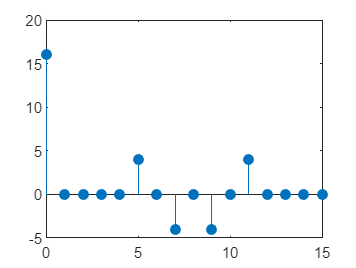

%set autocorrelations for f_bar
reg_plus_f_bar_auto = zeros(1,16);
reg_shift = f_bar;


for k = 1:16
    for i = 1:16
        if(reg_shift(i) == f_bar(i));
            reg_plus_f_bar_auto(1,k) = reg_plus_f_bar_auto(1,k) + 1;
        else (reg_shift(i) ~= f_bar(i));
            reg_plus_f_bar_auto(1,k) = reg_plus_f_bar_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_f_bar_auto,"filled");

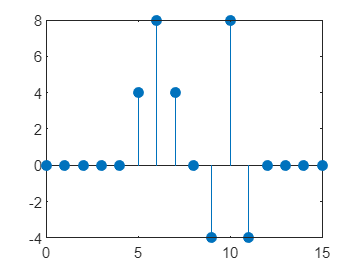

%set crosscorrletion for f and f_bar
reg_plus_f_cross = zeros(1,16);

for k = 1:16
    for i = 1:16
        if(f(i) == f_bar(i));
            reg_plus_f_cross(1,k) = reg_plus_f_cross(1,k) + 1;
        else (f(i) ~= f_bar(i));
            reg_plus_f_cross(1,k) = reg_plus_f_cross(1,k) - 1;
        end    
    end
    f_bar = circshift(f_bar,1);
end

stem(t,reg_plus_f_cross,"filled");

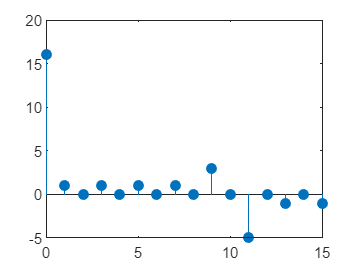

%aperiodic sequence
%set autocorrelations for f
reg_plus_ap_f_auto = zeros(1,16);
reg_shift = f;

for k = 1:16
    for i = k:16
        if(f(i) == reg_shift(i));
            reg_plus_ap_f_auto(1,k) = reg_plus_ap_f_auto(1,k) + 1;
        else (f(i) ~= reg_shift(i));
            reg_plus_ap_f_auto(1,k) = reg_plus_ap_f_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_ap_f_auto,"filled");

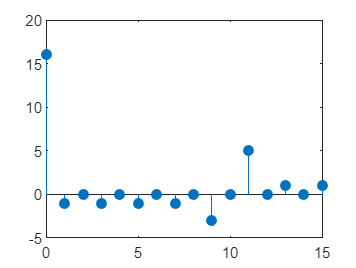

%set autocorrelations for f_bar
reg_plus_ap_f_bar_auto = zeros(1,16);
reg_shift = f_bar;


for k = 1:16
    for i = k:16
        if(reg_shift(i) == f_bar(i));
            reg_plus_ap_f_bar_auto(1,k) = reg_plus_ap_f_bar_auto(1,k) + 1;
        else (reg_shift(i) ~= f_bar(i));
            reg_plus_ap_f_bar_auto(1,k) = reg_plus_ap_f_bar_auto(1,k) - 1;
        end    
    end
    reg_shift = circshift(reg_shift,1);
end

stem(t,reg_plus_ap_f_bar_auto,"filled");

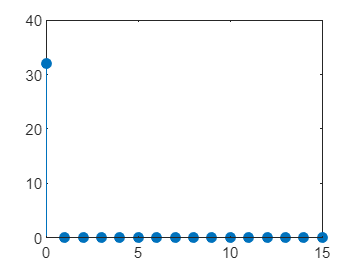

f_plus = reg_plus_ap_f_bar_auto + reg_plus_ap_f_auto;
stem(t,f_plus,"filled");

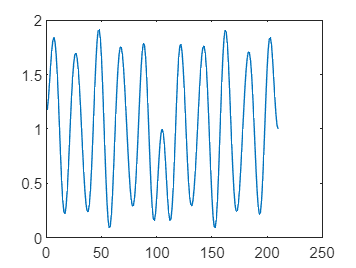

%To calculate the Pc(t)
sample = 210;
for T = 1:sample;
    t = T / sample;
    for u = 1:15
        %summation to caclulate
        Pc(1,1) = 16;
        Pc(1,u+1) = 2*reg_plus_ap_f_auto(1,u+1)*cos(2*pi*t*u);
        Pc_sum = sum(Pc);
        
        %integral to caclulate 
        Pc_function = @(t) 16 + 2*reg_plus_ap_f_auto(1,u+1)*cos(2*pi*t*u);
        Pc_avg = 1/t*integral(Pc_function,0,t);
    end
    PAPR(1,T) = Pc_sum/Pc_avg;
end
PAPR_MAX = max(PAPR);
plot(PAPR);